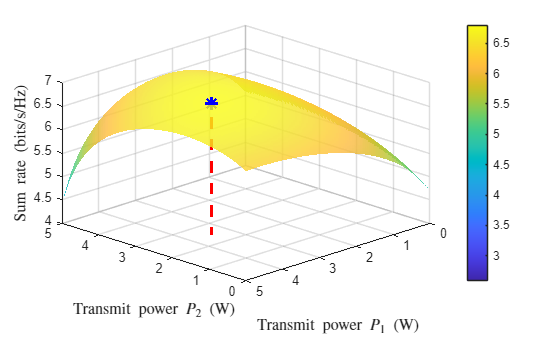

% Parameters
g = [1, 0.5, 2.5];  % Channel gains for p1, p2, p3
PT = 10;             % Total power budget
res = 200;           % Resolution for smooth surface

% Create grid of p2 and p3 values
[p2, p3] = meshgrid(linspace(0, PT, res), linspace(0, PT, res));
p1 = PT - p2 - p3;

% Mask invalid allocations where p1 < 0
valid = (p1 >= 0);

% Compute sum rate only for valid (feasible) allocations
C = nan(size(p1));  % initialize with NaNs
C(valid) = log2(1 + g(1)*p1(valid)) + log2(1 + g(2)*p2(valid)) + log2(1 + g(3)*p3(valid));

% Find the maximum sum rate and corresponding indices
[maxC, idx] = max(C(:));
[opt_i, opt_j] = ind2sub(size(C), idx);

% Extract optimal p2, p3, and p1 values
p1_opt = p1(opt_i, opt_j);
p2_opt = p2(opt_i, opt_j);
p3_opt = p3(opt_i, opt_j);

% Plot the surface
figure;
surf(p2, p1, C, 'EdgeColor', 'none', 'FaceAlpha', 0.8);
xlabel('$\mathrm{Transmit\ power\ } P_2\ (\mathrm{W})$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('$\mathrm{Transmit\ power\ } P_1\ (\mathrm{W})$', 'Interpreter', 'latex', 'FontSize', 12);
zlabel('$\mathrm{Sum\ rate\ } (\mathrm{bits/s/Hz})$', 'Interpreter', 'latex', 'FontSize', 12);
% title(['\textbf{Sum Rate vs. $p_2$ and $p_1$} ($P_T = ', num2str(PT), '$)'], ...
%     'Interpreter', 'latex', 'FontSize', 14);

view(45, 30); grid on; colorbar;
set(gca, 'XDir', 'reverse'); set(gca, 'YDir', 'reverse');

% Axis limits and ticks
xlim([0 5]); ylim([0 5]); zlim([4 7]);
xticks(0:1:5); yticks(0:1:5); zticks(4:0.5:7);

hold on;

% Plot optimal point as a blue star
plot3(p2_opt, p1_opt, maxC, 'b*', 'MarkerSize', 10, 'LineWidth', 2);

% Vertical dashed line from optimal point to base
plot3([p2_opt, p2_opt], [p1_opt, p1_opt], [0, maxC], 'r--', 'LineWidth', 2);

% Annotate the optimal point with LaTeX
annotation_str = sprintf(['\\begin{tabular}{l}', ...
    '\\textbf{Optimal power allocation scheme:} \\\\', ...
    '$P_1 = %.1f$, $P_2 = %.1f$, $P_3 = %.1f$', ...
    '\\end{tabular}'], p1_opt, p2_opt, p3_opt);

hold off;

% Parameters
g = [3, 1, 3];  % Channel gains for p1, p2, p3
PT = 10;             % Total power budget
res = 200;           % Resolution for smooth surface

% Create grid of p2 and p3 values
[p2, p3] = meshgrid(linspace(0, PT, res), linspace(0, PT, res));
p1 = PT - p2 - p3;

% Mask invalid allocations where p1 < 0
valid = (p1 >= 0);

% Compute sum rate only for valid (feasible) allocations
C = nan(size(p1));  % initialize with NaNs
C(valid) = log2(1 + g(1)*p1(valid)) + log2(1 + g(2)*p2(valid)) + log2(1 + g(3)*p3(valid));

% Find the maximum sum rate and corresponding indices
[maxC, idx] = max(C(:));
[opt_i, opt_j] = ind2sub(size(C), idx);

% Extract optimal p2, p3, and p1 values
p1_opt = p1(opt_i, opt_j);
p2_opt = p2(opt_i, opt_j);
p3_opt = p3(opt_i, opt_j);

% Plot the surface
figure;
surf(p2, p1, C, 'EdgeColor', 'none', 'FaceAlpha', 0.8);
xlabel('$\mathrm{Transmit\ power\ } P_2\ (\mathrm{W})$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('$\mathrm{Transmit\ power\ } P_1\ (\mathrm{W})$', 'Interpreter', 'latex', 'FontSize', 12);
zlabel('$\mathrm{Sum\ rate\ } (\mathrm{bits/s/Hz})$', 'Interpreter', 'latex', 'FontSize', 12);
% title(['\textbf{Sum Rate vs. $p_2$ and $p_1$} ($P_T = ', num2str(PT), '$)'], ...
%     'Interpreter', 'latex', 'FontSize', 14);

view(45, 30); grid on; colorbar;
set(gca, 'XDir', 'reverse'); set(gca, 'YDir', 'reverse');

% Axis limits and ticks
xlim([0 5]); ylim([0 5]); zlim([5 10]);
xticks(0:1:5); yticks(0:1:5); zticks(5:1:10);

hold on;

% Plot optimal point as a blue star
plot3(p2_opt, p1_opt, maxC, 'b*', 'MarkerSize', 10, 'LineWidth', 2);

% Vertical dashed line from optimal point to base
plot3([p2_opt, p2_opt], [p1_opt, p1_opt], [0, maxC], 'r--', 'LineWidth', 2);

% Annotate the optimal point with LaTeX
annotation_str = sprintf(['\\begin{tabular}{l}', ...
    '\\textbf{Optimal power allocation scheme:} \\\\', ...
    '$P_1 = %.1f$, $P_2 = %.1f$, $P_3 = %.1f$', ...
    '\\end{tabular}'], p1_opt, p2_opt, p3_opt);

hold off;

% Parameters
g = [1, 3, 1];  % Channel gains for p1, p2, p3
PT = 10;             % Total power budget
res = 200;           % Resolution for smooth surface

% Create grid of p2 and p3 values
[p2, p3] = meshgrid(linspace(0, PT, res), linspace(0, PT, res));
p1 = PT - p2 - p3;

% Mask invalid allocations where p1 < 0
valid = (p1 >= 0);

% Compute sum rate only for valid (feasible) allocations
C = nan(size(p1));  % initialize with NaNs
C(valid) = log2(1 + g(1)*p1(valid)) + log2(1 + g(2)*p2(valid)) + log2(1 + g(3)*p3(valid));

% Find the maximum sum rate and corresponding indices
[maxC, idx] = max(C(:));
[opt_i, opt_j] = ind2sub(size(C), idx);

% Extract optimal p2, p3, and p1 values
p1_opt = p1(opt_i, opt_j);
p2_opt = p2(opt_i, opt_j);
p3_opt = p3(opt_i, opt_j);

% Plot the surface
figure;
surf(p2, p1, C, 'EdgeColor', 'none', 'FaceAlpha', 0.8);
xlabel('$\mathrm{Transmit\ power\ } P_2\ (\mathrm{W})$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('$\mathrm{Transmit\ power\ } P_1\ (\mathrm{W})$', 'Interpreter', 'latex', 'FontSize', 12);
zlabel('$\mathrm{Sum\ rate\ } (\mathrm{bits/s/Hz})$', 'Interpreter', 'latex', 'FontSize', 12);
% title(['\textbf{Sum Rate vs. $p_2$ and $p_1$} ($P_T = ', num2str(PT), '$)'], ...
%     'Interpreter', 'latex', 'FontSize', 14);

view(45, 30); grid on; colorbar;
set(gca, 'XDir', 'reverse'); set(gca, 'YDir', 'reverse');

% Axis limits and ticks
xlim([0 5]); ylim([0 5]); zlim([3 8]);
xticks(0:1:5); yticks(0:1:5); zticks(3:1:8);

hold on;

% Plot optimal point as a blue star
plot3(p2_opt, p1_opt, maxC, 'b*', 'MarkerSize', 10, 'LineWidth', 2);

% Vertical dashed line from optimal point to base
plot3([p2_opt, p2_opt], [p1_opt, p1_opt], [0, maxC], 'r--', 'LineWidth', 2);

% Annotate the optimal point with LaTeX
annotation_str = sprintf(['\\begin{tabular}{l}', ...
    '\\textbf{Optimal power allocation scheme:} \\\\', ...
    '$P_1 = %.1f$, $P_2 = %.1f$, $P_3 = %.1f$', ...
    '\\end{tabular}'], p1_opt, p2_opt, p3_opt);

hold off;